### Load soundfile

clear all;
addpath(['~/Documents/Courses/'...
    'ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/snd']);

[X, Fs] = audioread('pori.wav');

# Signal Sementation Measurement (manual)

n = 100:150:2000;             % time points which to measure in ms
M = 100 * ones(length(n), 1); % durations of segments to measure in ms

% convert miliseconds to samples
n = round(n ./1000 .*Fs); 
M = round(M ./1000 .*Fs);

seg = {};

for i = 1:length(n)
    st = n(i);
    len = M(i);
    seg{i} = X(st:st+len-1);
end

# LPC spectral estimate

#### Run above segmentation to populate 'seg' variable.

lpcOrder = 6;       % LPC Allpole coeff order
resolution = 1024;   % freqz resolution of LPC filter (number of points to generate)

nSig = length(seg);  % number of signals to analyze
specEnv = zeros(resolution, nSig); % a matrix to hold all the segments' spectral envs

for i = 1:nSig
    [lpc_coefs, residual] = lpc(seg{i}, lpcOrder);
    [H, w] = freqz(1, lpc_coefs, resolution);
    specEnv(:, i) = mag2db(abs(H));
end

% normalize to channel peak
specNorm = db2mag(specEnv);
specNorm = specNorm ./ max(specNorm); 
specNorm = mag2db(specNorm);

# Plot spectrum of LPC spectrum estimate

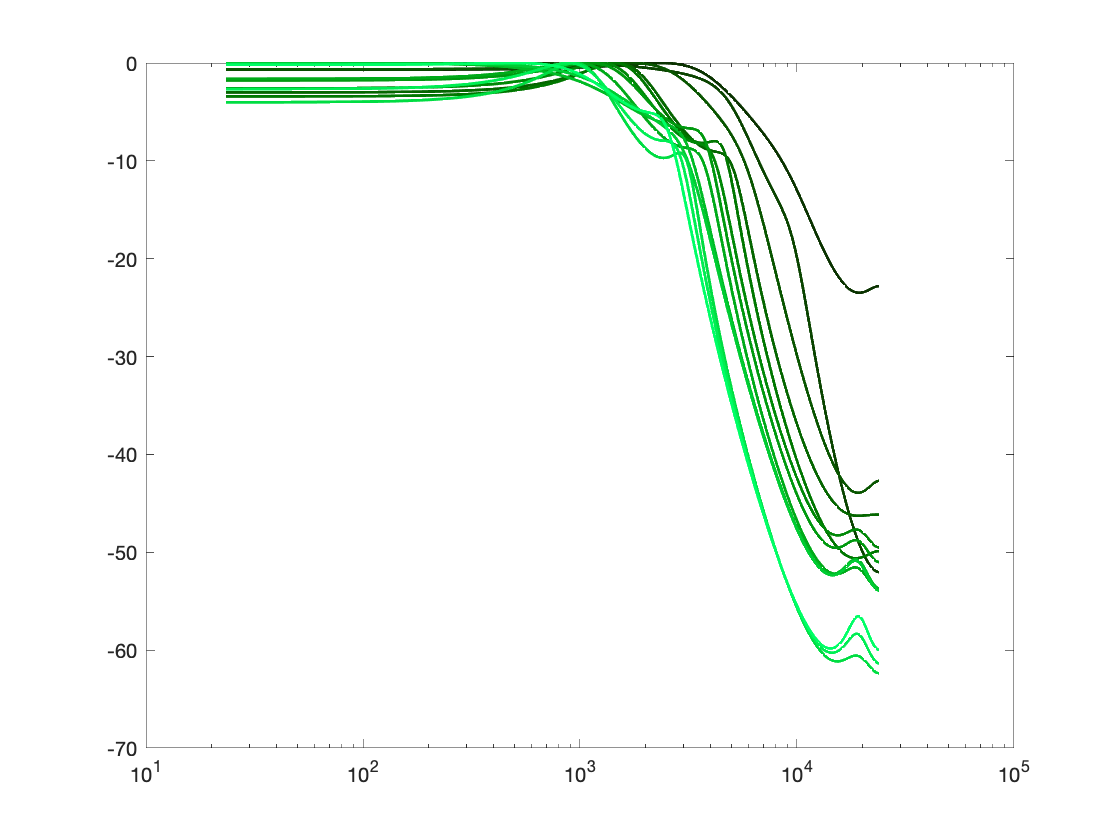

% Frequency bins
f = (w/pi) * (Fs/2);
plt = semilogx(f, specNorm, "LineWidth", 1.5);

% keep track of the plots for legend management
plts = {}; 
plts{1} = plt;

% Colors
hueStart = 0.3;
hueSpan = 0.1;
hue = linspace(hueStart,hueStart+hueSpan,nSig); % hue
sat = linspace(1,1,nSig);     % saturation
val = linspace(0.2,1,nSig);   % value
hsv = [hue' sat' val']; 
rgb = hsv2rgb(hsv);
colororder(rgb);

% % Legend - uncomment if not including rolloff markers in plot following
% legend("Location", "SouthWest");
% legend('Position',[0.18 0.2 0.15 0.2]);
% axis tight;

hold on;

# Plot spectral peaks and -XdB rolloff point

Finds the spectral maximum, and detects the point where low pass rolloff matches a specified value.

- Reference uses -20db rolloff point, LPC oder = 6

***Run LPC spectral estimate before this block.**

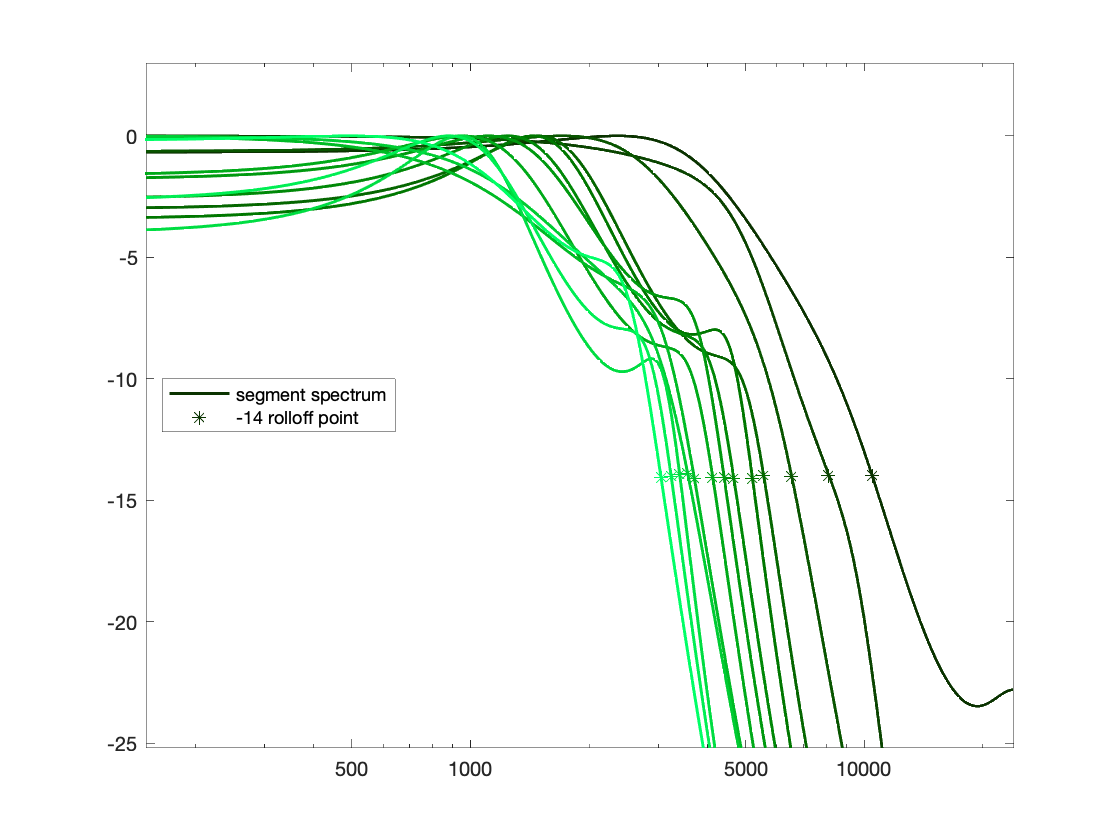

rolloff = -14; % rolloff to detect, in dB
minFrq = 150;
minFrqIdx = floor(minFrq/(Fs/2) * resolution);

srchSpec = specNorm(minFrqIdx:end, :);
[ d, ix ] = min(abs(srchSpec - rolloff));
ix = ix + minFrqIdx-1; % restore index
f = w(ix)/pi* (Fs/2);

r=ix;
c=1:size(specNorm,2);
pnts = specNorm(sub2ind(size(specNorm),r,c)); % cutoff values in each segment

for i = 1:length(pnts)
    plt = semilogx( ...
        f(i), pnts(i), ...
        "LineStyle", "none", "Marker", "*" ...
    );
    plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
    plts{i+1} = plt; % +1: plts{1} is the array of line plots 
end

% colors
colororder([rgb; rgb]); % repeated so line and marker colors match

legend([ ...
    plts{1}(1) ... % first of the line plots
    plts{2} ...    % first of the rolloff markers
    ],[ ...
    "segment spectrum" ...
    string(rolloff) + " rolloff point" ...
    ]);
legend("Location", "West");
% legend('Position',[0.18 0.2 0.15 0.2]);

ylim([rolloff*1.8 2]);
xlim([minFrq Fs/2]);
xticks([500 1000 5000 10000])


hold off;

# Plot segmented FFT

Uses single or multi-segment fft function below

% plotOneFFT(seg{1}, Fs)
plotMultiFFT(seg, 512, Fs)

legend()

# function: PlotOneFFT, PlotMultiFFT 

- Note: **fftshift()** shifts bins to put 0Hz at the center (odd N) or center +1 (even N)

function plotOneFFT(signal, N, Fs)
    zoom = [0 Fs/2];         % "zoom in" on this freq range
    H = fft(signal, N);
    mag = abs(H)*2/N;
    mag = fftshift(mag);
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N); % spectrum 0 -> Nyquist
    mag = mag(pidx);
    mag = mag2db(mag);
    f = linspace(0, Fs/2, length(mag));
    
%     stem(f, mag);
    semilogx(f, mag);
    xlim(zoom);              % zoom via plot limits
    ylim([-150 -50])
end

function plotMultiFFT(signalCell, N, Fs)
    % plotMultiFFT(signalCell, N, Fs)
    %    [input]
    % signalCell: a cell array containing signals to perform FFT
    %          N: FFT size
    %         Fs: sample rate of signal
    
    mags = zeros(N, length(signalCell)); % matrix to hold FFT analysis
    
    % "zoom in" on this freq range (via xlim)
    % Change this is you want a specific freq range
    zoom = [0 Fs/2];                     
    
    nSig = length(signalCell);
    for i=1:nSig
        mags(:,i) = fft(signalCell{i}, N);
    end
    mags = abs(mags)*2/N;
    mags = fftshift(mags);    
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N);        % spectrum 0 -> Nyquist
    mags = mags(pidx, :);
    mags = mags./max(max(mags));    % normalize spectra
    mags = mag2db(mags);
%     mags = mags./max(mags);
    
    f = linspace(0, Fs/2, length(mags)); % bin frequencies 
    semilogx(f, mags);
    xlim(zoom);
    ylim([-80 0]);
end